## TCLab Function Help

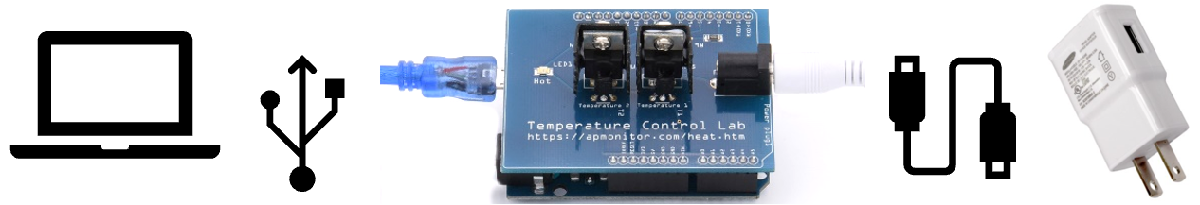

**Connect**

`lab = tclab` Connect and create new lab object

**LED**

`lab.LED()` Percentage of output light for **Hot** Light.

**Heaters**

`lab.Q1()` and `lab.Q2()` Percentage of power to heaters.

**Temperatures**

`lab.T1` and `lab.T2` Value of current heater temperatures in Celsius.

**Shut down**

`lab.off()` turns off heaters.

**Disconnect**

`clear all` or `clear lab` to disconnect from lab.

**Matlab**

Install [Matlab](https://www.mathworks.com/products/matlab.html) with the Arduino Support Package for Matlab and Simulink (2 separate Add-ons).

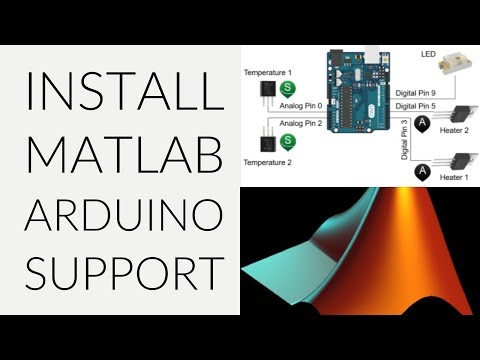

[Click here to watch the video.](https://www.youtube.com/watch?v=DFvUJh8AYjE)

There are [additional instructions on installing Matlab and managing modules](https://apmonitor.com/che263/index.php/Main/MatlabIntroduction).

**Octave**

A freely available alternative to Matlab is [GNU Octave](https://www.gnu.org/software/octave/).

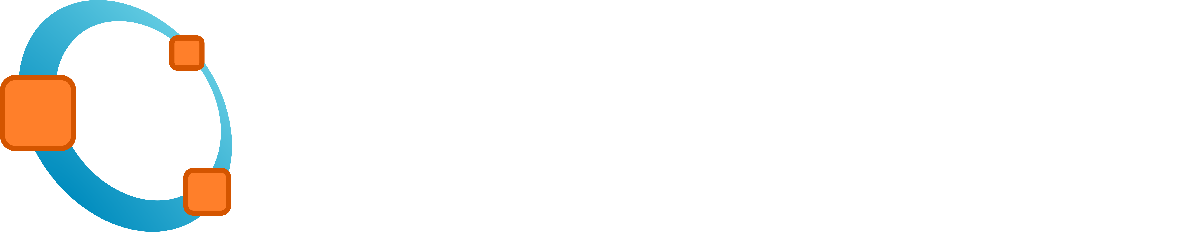

Octave has very similar syntax to Matlab and can also be used for this course. Install the Arduino support package from the Octave terminal with:

**How to Run a Cell**

Use the symbol to run the needed cell, left of the program. If you don't see a symbol, try selecting the cell and holding `Ctrl`, then pressing `Enter`. Another option is clicking the "Run" button at the top of the page when the cell is selected.

**Retrieve Temperature Control Lab Code** `tclab.m`

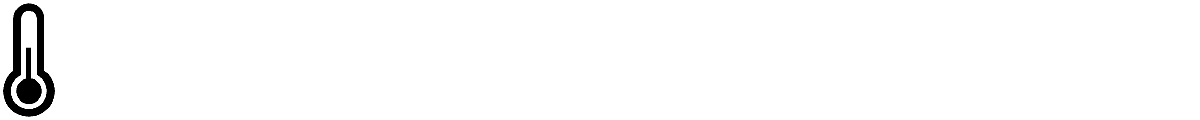

You need the TCLab to do the exercises. As a first step, plug in the TCLab (USB blue cable only) and download the `tclab.m` package by running the cell below (`Ctrl+Enter`). The `tclab.m` file will appear in the same folder where you are running `01. Overview.ipynb`. The source file `tclab.m` is from the [URL on GitHub](https://github.com/APMonitor/begin_matlab/blob/master/tclab.m) and may already be in your run directory. Matlab and Octave have different methods (`websave` or `urlwrite`) to retrieve an Internet file. We first `try` the Match function and then `catch` any errors by trying the Octave function.

file = 'tclab.m';
url = 'https://raw.githubusercontent.com/APMonitor/begin_matlab/master/tclab.m';

try
    % for MATLAB
    websave(file,url);
catch
    % for Octave
    urlwrite(url,file);
end

**Connection Check**

The following code connects, reads temperatures 1 and 2, sets heaters 1 and 2, turns on the LED to 45%, and then disconnects from the TCLab. If an error is shown try unplugging your lab or restarting the Jupyter kernel from the notebook menu.

clear all
lab = tclab;
disp('Temperatures')
disp([lab.T1,lab.T2])
disp('Turn on heaters')
lab.Q1(50); lab.Q2(40);
lab.LED(45);
pause(2); disp('Paused 2 sec')
disp(lab.off())
clear lab

**Errors**

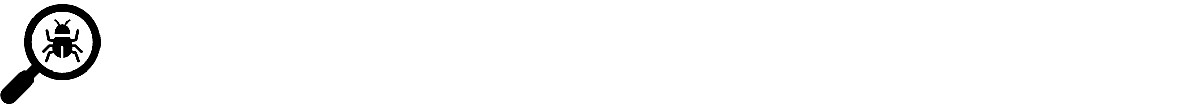

Submit an error to us at support@apmonitor.com so we can fix the problem and add it to this list. There is also a list of [troubleshooting items with frequently asked questions](https://apmonitor.com/pdc/index.php/Main/ArduinoSetup). If you get the error about already having an open connection to the TCLab, try restarting the **kernel** and `clear lab`. Go to the top of the page to the **Kernel** tab, click it, then click restart.